clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',6);
set(0,'DefaultTextFontsize',6);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

figsize = [10 15 5.3 3.5];
figpos = [0.18 0.25 0.75 0.65];
lw = 0.8;

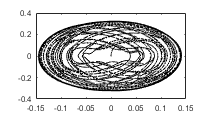

load('data\fig4_inidata.mat');

Nrlist = [20 50 500];
colors = linspecer(5);

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

k = boundary(trainregion(:,1), trainregion(:,2), 0.5);
p(1) = plot(trainregion(k,1), trainregion(k,2), 'k', 'LineWidth', 1.1);
hold on;
s = scatter(trainregion(:,1), trainregion(:,2), [], [0 0 0], 'filled', 'SizeData', 1);
hold on;


errors = [inidata{1}(:,3); inidata{2}(:,3); inidata{3}(:,3); inidata{4}(:,3); inidata{5}(:,3)];
idx = find(errors<1000);
errormax = 2*max(errors(idx));
% errormax = 20000;

for i = 1:5
    ini_data = inidata{i};
    % error = ini_data(:,3);
    idx = find(ini_data(:,3)<1000 & ini_data(:,1)>-3 & ini_data(:,1)<3 & ini_data(:,2)>-23  & ini_data(:,2)<23);
    ini_datasort = ini_data(idx,:);
    % ini_datasort = ini_data;
    k = boundary(ini_datasort(:,1), ini_datasort(:,2), 0.5);
    
    % for j = 1:size(ini_datasort, 1)
    %     s = scatter(ini_datasort(j,1), ini_datasort(j,2), [], colors(i,:), 'filled', 'SizeData', 5);
    %     s.MarkerFaceAlpha = (ini_datasort(j,3)/errormax);
    % end

    s = scatter(ini_datasort(:,1), ini_datasort(:,2), [], colors(i,:), 'filled', 'SizeData', 5);
    s.AlphaData = (ini_datasort(:,3));
    s.MarkerFaceAlpha = 'flat';

    hold on;
    p(i+1) = plot(ini_datasort(k,1), ini_datasort(k,2), 'Color', colors(i,:), 'LineWidth', 1.1);
    hold on;
end

xlim([-3 3]);
ylim([-20 20]);
xlabel('$\theta$ (rad)','interpreter','latex');
ylabel('$\dot{\theta}$ (rad/s)','interpreter','latex');

leg = legend(p(3:end), 'ESN10', 'ESN20', 'ESN50', 'ESN500');
% leg.Box = "off";
leg.ItemTokenSize = [10 15];
leg.Position = [0.76 0.61 0.2 0.2];
title('Basin of Attraction');

ah1 = axes('position',get(gca,'position'),'visible','off');
leg2 = legend(ah1, p(1:2), 'Training', 'LQR1');
leg2.ItemTokenSize = [10 15];
leg2.Position = [0.23 0.28 0.2 0.2];

